# Assignment 2

Simulate a 3-D multivariate T that is independent, not identically distributed.

rng('default')

T = 2000;
rep = 200;

df_vec = linspace(6,3,T);
% Random symmetric sigma
SIGMA = [1 -0.8 0.3; -0.8 0.5 1; 0.3 1 0.7];
% Make sigma positive semi definite
SIGMA = SIGMA*SIGMA.';

% Make location vectors
mu = [-1,0,1];

% Grid of different values of rhos
rhos = 0.2:0.1:1;

## Using MMF to estimate for 1 i.d. MVT

df_estimated = zeros(1,length(rhos));

t = zeros(3,T);
for i=1:T
    R = mvtrnd(SIGMA,df_vec(i));
    R = R+mu;
    t(:,i) = R;
end

for i=1:length(rhos)
    tvec=(1:T).'; 
    omega=(T-tvec+1).^(rhos(i)-1);
    w=T*omega'/sum(omega);
    [mu_estimated, nu_estimated, sigma_estimated, ~, ~, ~]=iterate_studentT(t,w,'MMF',100,0,0,0,1);
    df_estimated(i) = nu_estimated;
end

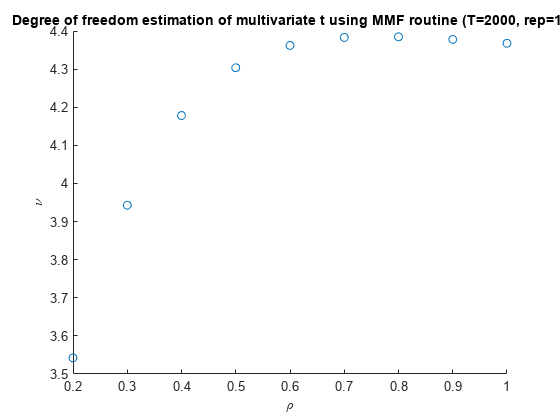

scatter(rhos,df_estimated)
xlabel('\rho')
ylabel('\nu')
title('Degree of freedom estimation of multivariate t using MMF routine (T=2000, rep=1)')

## Simulate 200 replications with MMF routine

df_estimated = zeros(rep,length(rhos));

f = waitbar(0, 'Starting');
profile on
for i=1:rep
    waitbar(i/rep, f, sprintf('Progress: %d %%',floor(i/rep*100)));
    
    t = zeros(3,T);
    df_vec = linspace(6,3,T);

    % independent distributed with different seeds
    rng(i);
    for j=1:T
        R = mvtrnd(SIGMA,df_vec(j));
        R = R+mu;
        t(:,j) = R;
    end

    for j=1:length(rhos)
        tvec=(1:T).'; 
        omega=(T-tvec+1).^(rhos(j)-1);
        w=T*omega'/sum(omega);
        [mu_estimated, nu_estimated, sigma_estimated, ~, ~, ~]=iterate_studentT(t,w,'MMF',100,0,0,0,1);
        df_estimated(i,j) = nu_estimated;
    end
end
profile off
close(f)

profile viewer
% 43.582s total time

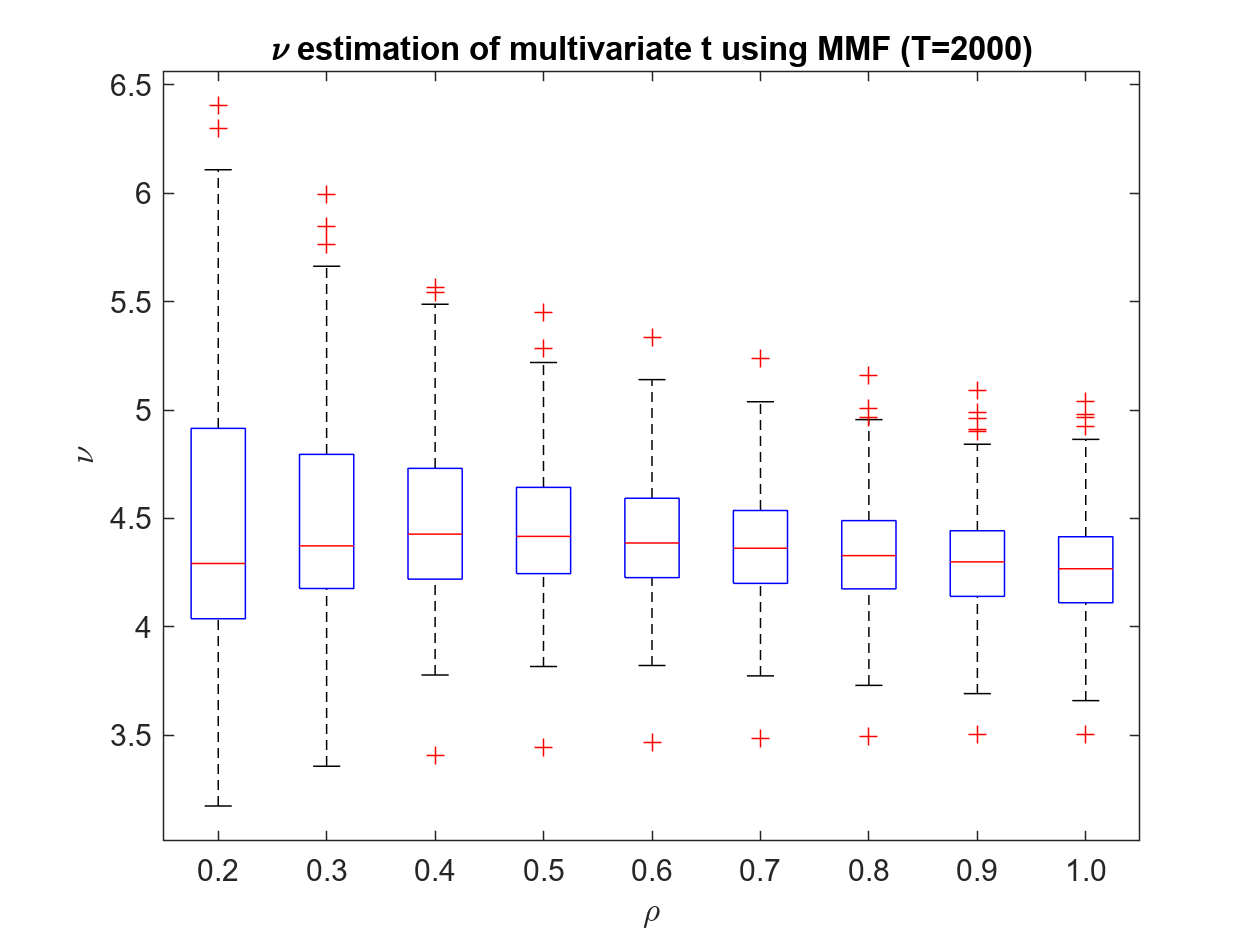

boxplot(df_estimated,'Labels',{'0.2','0.3','0.4','0.5','0.6','0.7','0.8','0.9','1.0'})
xlabel('\rho')
ylabel('\nu')
title('\nu estimation of multivariate t using MMF (T=2000)')

## Simulate 200 replications with brute force MLE

rep = 200;
df_estimated = zeros(rep,length(rhos));

f = waitbar(0, 'Starting');
profile on
for i=1:rep
    waitbar(i/rep, f, sprintf('Progress: %d %%',floor(i/rep*100)));
    
    t = zeros(3,T);
    df_vec = linspace(6,3,T);

    % independent distributed with different seeds
    rng(i);
    for j=1:T
        R = mvtrnd(SIGMA,df_vec(j));
        R = R+mu;
        t(:,j) = R;
    end

    for j=1:length(rhos)
        [nu_estimated, mu_estimated, sigma_estimated]=mle_MVT(t,rhos(j));
        df_estimated(i,j) = nu_estimated;
    end
end
profile off
close(f)

profile viewer
% 260.506s total time

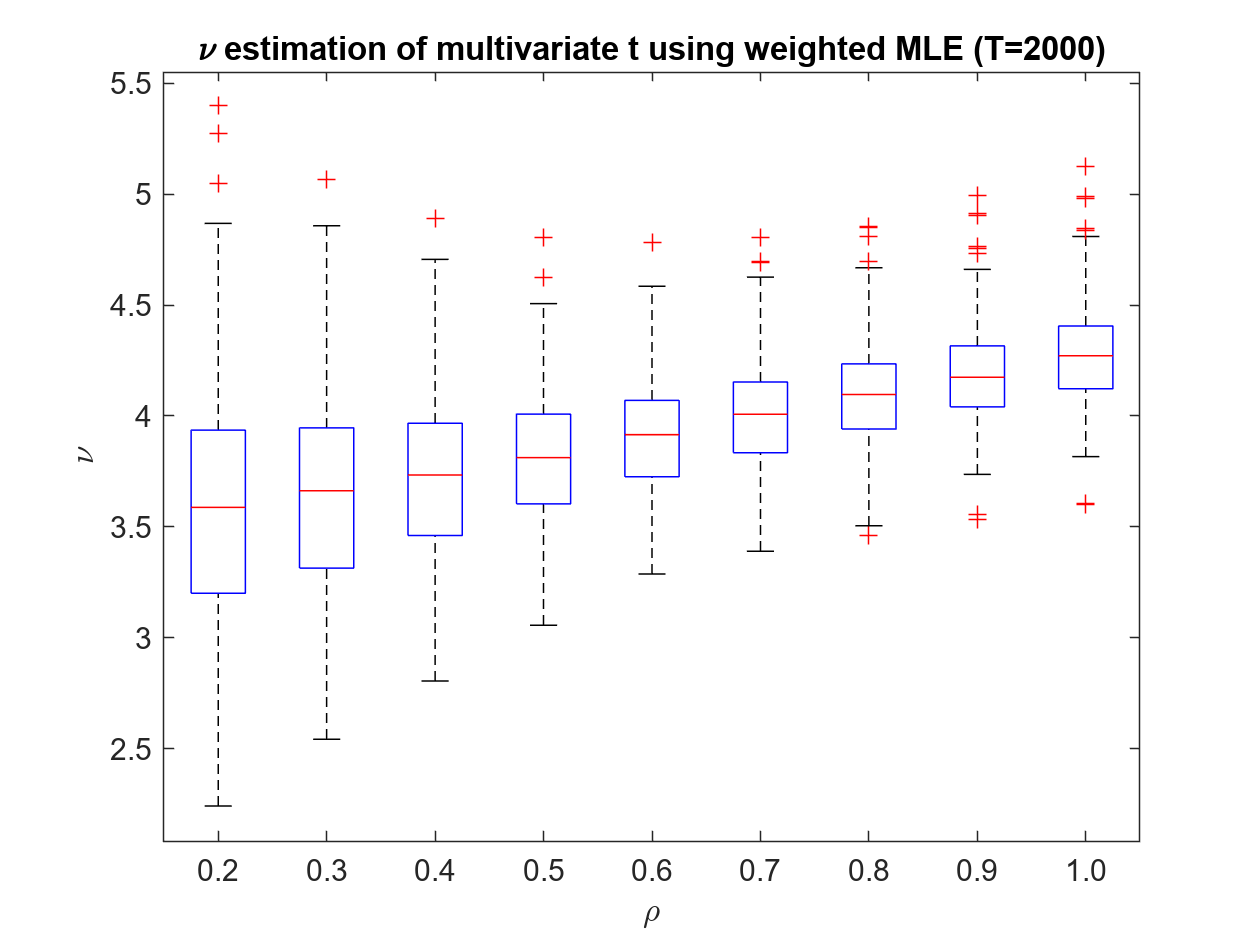

boxplot(df_estimated,'Labels',{'0.2','0.3','0.4','0.5','0.6','0.7','0.8','0.9','1.0'})
xlabel('\rho')
ylabel('\nu')
title('\nu estimation of multivariate t using weighted MLE (T=2000)')